# Part 3: Explore `penguins`

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

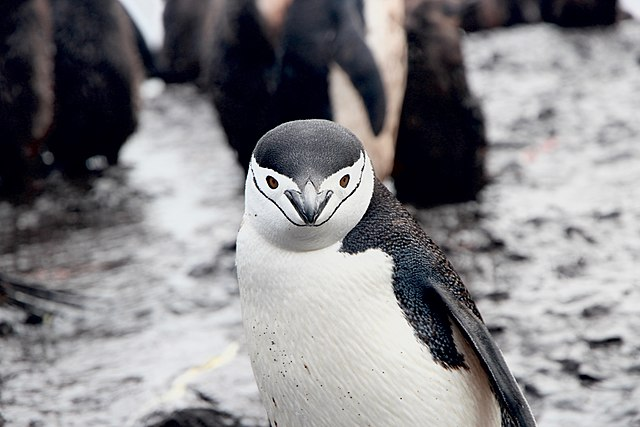

A chinstrap penguin displaying his [chinstrap](https://commons.wikimedia.org/wiki/File:Chinstrap_Penguin_(Unsplash).jpg). 

In this section, we'll explore `penguins` and figure out what we have to work within our dataset. You should first go through the [Access Data script](matlab: edit S2_AccessData.mlx). If you already did this but the `penguins` variable is no longer in your workspace, this block of code will add `penguins` to your workspace: 

filename = "penguins.csv";
penguins = readtable(filename);

Let's begin by exploring what we have in this dataset that we can use to describe our penguins. 

## 1: Variable names

There are several ways to figure this out. First, you can just read the table by double-clicking on the `penguins` variable in the Workspace. You can also run: 

summary(penguins)

[`summary()`](https://www.mathworks.com/help/matlab/ref/table.summary.html) is another built-in MATLAB® function and it tells us what the variables in our table are. So for example, we have information about body mass, sex, bill length, and more in our dataset! 

*Tip*: if you ever want to know more about a function, such as `summary`, you can utilize the Help browser. 

  Try typing `doc` in the cell below:

A Help Center window will pop up. Edit the code to say `doc summary`, and the documentation page for the summary function will appear. 

Next, let's look at how much data we have to work with here. 

## 2: Table Size

As discussed in the [MATLAB Onramp](https://matlabacademy.mathworks.com/R2023a/portal.html?course=gettingstarted#chapter=5&lesson=2), when you have a matrix or a table, the data is stored in rows and columns. 

We can figure out the size of our table by using the built-in function [`size()`](https://www.mathworks.com/help/matlab/ref/size.html). This gives the number of rows, 344, followed by the number of columns, 7: 

size(penguins)

We can set output variables to the function [`size()`](https://www.mathworks.com/help/matlab/ref/size.html) so that the number of rows and columns are saved as variables: 

[rows, cols] = size(penguins) 

So we know we have 344 rows and 7 columns. Each row contains all the data we have for an individual penguin. Each column contains the individual variables or things that we know about each penguin, such as species, island, body mass, and more.

***A quick note on indexing: ***

We can index into most MATLAB datasets to retrieve certain rows or columns. [Indexing](https://www.mathworks.com/help/matlab/math/array-indexing.html) simply refers to our ability to access or modify specific elements of a data structure. We'll do a quick demonstration here, but try out the section of the [Fundamentals of Programming course](https://www.mathworks.com/matlabcentral/fileexchange/103225-fundamentals-of-programming) called "Arrays" to get more practice with indexing. 

If we want to pull a single value out of our table, we have to specify the row and column of the datapoint we want to see or modify. 

For example, lets find the element of `penguins` that is in row 56 and column 3: 

row56_col3 = penguins(56,3) 

Column 3 corresponds to bill length, so this value is the bill length of the 56th penguin, in millimeters. 

If we want to look at just the first 10 rows of `penguins` we will specify rows as `1:10`. If we want to look at all the columns or variables for these first 10 penguins, we will specify that we want to see all columns by using the colon operator, `:`.  

first10rows = penguins (1:10, :)

  Pull out the first 20 rows and the first 3 columns of `penguins`: 

If we want to focus in on one variable that describes our penguins and look at the values for all penguins: 

sex = penguins(:, end)

This returns all penguins (all rows), but only the last column, which gives us each penguin's sex. 

## 3: Data types 

It's always important to ask what type of data you have, as this affects how you interact with it! Data is stored in a variety of types in programming languages such as MATLAB. Having different data types allows the computer to understand and interpret different kinds of data. The three most basic ways data is stored are: 1) as a number (1, 2, 3, 4.65, etc), 2) as a string ("a", "i love dogs"), and 3) as a logical or Boolean operator (i.e 1 or 0, true or false). These data types can be stored in many different ways, such as our penguin table! [This video](https://www.mathworks.com/videos/introducing-matlab-fundamental-classes-data-types-101503.html) is an introduction to fundamental data types in MATLAB, and [this MATLAB module](https://www.mathworks.com/matlabcentral/fileexchange/115900-programming-organizing-data) lets you practice working with data types. 

To check out the data type of the variable you are working with you can try: 

whos penguins 

Which tells you some information about the size and the class (or data type) of our variable. 

You can also explicitly ask for the class of your variable by typing: 

class(penguins)

which tells you that `penguins` is a table! 

There are several data types we can use in MATLAB. One is (of course), the [table](https://www.mathworks.com/help/matlab/matlab_prog/create-a-table.html), which stores columns of data in variables. These variables can have different data types, which we will look at in a moment. One way to access the data in a table is via [' dot notation'](https://www.mathworks.com/help/matlab/matlab_prog/create-a-table.html). The syntax `table.variable` will return the contents of that variable's column as an array. For example: 

bill_length = penguins.bill_length_mm;

If you want to see what the `bill_length` array looks like, you can remove the semicolon so the output prints, or navigate to your workspace and double click `bill_length`. 

  Find the `class()` of the new variable `bill_length`: 

`bill_length` an array of 'doubles'. [Doubles](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) refer to a way that numbers can be stored, and is the default way that MATLAB stores numbers that contain a decimal point. (This means that we can perform mathematic operations with the contents of `bill_length`.)

So what about other data types?

First let's access the column of `penguins` with species information (`penguins. species`) and assign it to the variable `species`: 

species = penguins.species;

  Find the `class()` of the new variable species: 

Now we have a [cell array](https://www.mathworks.com/help/matlab/cell-arrays.html), which is a way to store data of various sizes and types. 

We access the contents of a cell by using `{}`. 

For example: 

species_1 = species{1}

returns the contents of the first cell of `species.`

  Find the `class()` of the `species_1`: 

`species_1` is of class '[char](https://www.mathworks.com/help/matlab/ref/char.html)', another data type used for text! 

A tip for working with non-numeric data that might be stored in cell arrays or some other format is to create [categorical arrays](https://www.mathworks.com/help/matlab/categorical-arrays.html), which are much easier to work with. 

Try: 

penguins.species = categorical(penguins.species) 

Notice that in this case, we've changed the species column of the table itself rather than adding the contents of that column to a new variable.

   If you check the class of `penguins.species`, you'll notice that it switched from "cell array of character vectors" to "categorical".

## 4: Manipulating `penguins`

Now that we know a little bit about what kind of data we are working with, let's try manipulating our data. We'll first sort our table by bill length. 

#### Method 1: Use bulit-in tools to sort `penguins`

First, run this cell so that the table `penguins` appears as output:

penguins 

In the table that appears below your code block, you can click around and select different columns. Hover over the `bill_length_mm` header, and an arrow will appear. Click on the arrow and select **Sort Smallest to Largest**. 

  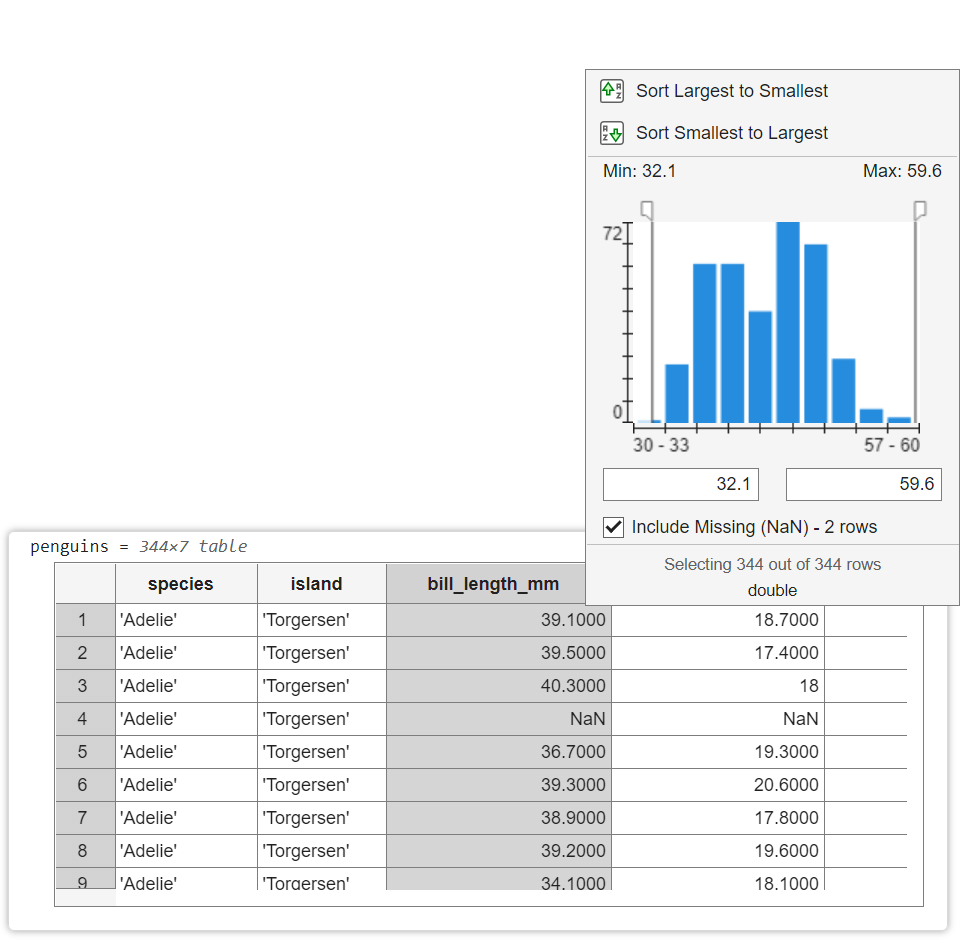

Notice how the table changes after sorting! 

The little chart that appeared when you clicked on the arrow next to bill length tells you that the minimum value is 32.1, and you can see that this is now the first value in the table! Row number 1 should now be occupied by the penguin with the smallest beak size. The longest-beaked penguin should have a beak length of 59.6 mm and be at the end of the table. You'll notice that the two animals for which there is no beak length (NaN values) are the actual last rows of the table. That's ok, we'll ignore those values for now. 

Also, notice that the table has a line beneath it called "code" which shows you what code you could use to generate this sorted table. Try clicking "Update Code" and see what happens to the code block above! MATLAB allows you to interact with the table directly, but also save the changes you make as lines of code so you can replicate those changes in the future.

#### Method 2: Sort `penguins` programatically 

[`sortrows()`](https://www.mathworks.com/help/matlab/ref/double.sortrows.html) is a MATLAB function we can use to sort an array of values. Again, let's sort bill length by smallest to largest. In this case, we are instructing the computer to sort `penguins` based on the bill length column. By default, the table will be sorted by smallest to largest. 

penguins = sortrows(penguins, "bill_length_mm")

But what if you want to go in the opposite direction? 

Try running; 

penguins = sortrows(penguins, "bill_length_mm", "descend")

In this case, we've told the computer a specific direction (descending) in which to sort the data. Notice how the table changes. 

*Tip: *You can use the tip from earlier and type `doc sortrows` to pull up the `sortrows()` documentation and see what all the options are. Alternatively, if you want to see what the options for the direction input to `sortrows()` are aside from `"descend"`, you can type: 

 and then hit **Tab** twice, you'll see what the `direction` options are, and you can simply click on one to change that input in your code!

So far you've loaded penguin data and you've learned how to play around with this data. In the next script, we'll learn how to visualize this data. 

[*Go to next script (Visualize Data)*](matlab: edit S4_VisualizeData.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)